# Image denoising using deep learning

**Goal:** Build and evaluate image denoising solutions using deep learning architectures. 

**Learning objectives:**

- Learn how to implement an Image Processing **workflow** in MATLAB 

- Learn how to implement and evaluate **contemporary** (deep-learning-based) image denoising techniques in MATLAB

- Get acquainted with representative **datasets** and problems in image denoising

## Part 1: Noise types and image quality metrics

### Effects of different noise types

[`imnoise()`](https://www.mathworks.com/help/images/ref/imnoise.html) allows you to add noise to an image. You can choose from different noise types: Gaussian, Poisson, salt-and-pepper.

**Suggested steps:**

- Load test image and add noise. 

- Try out a few noise types, and play with associated parameters.

- Visualize the image before and after adding noise. 

**Example code:**

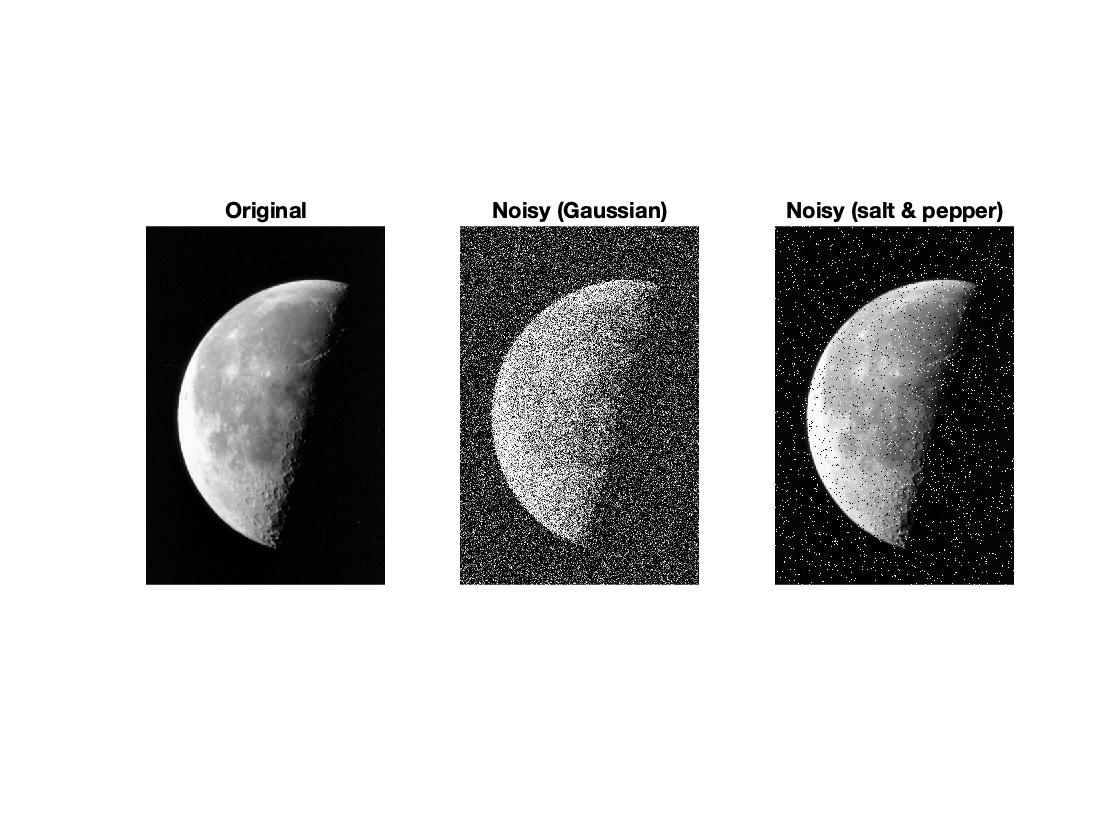

I = imread('moon.tif');
Jg = imnoise(I, 'gaussian', 0, 0.2);    % Add gaussian noise with zero mean and variance=0.2
Jsp = imnoise(I,'salt & pepper');       % Add salt-and-pepper noise

% Display images
figure('Name','Adding noise to an image');
subplot(1,3,1), imshow(I), title('Original')
subplot(1,3,2), imshow(Jg), title ('Noisy (Gaussian)')
subplot(1,3,3), imshow(Jsp), title ('Noisy (salt & pepper)')

### Assess different image quality metrics

*"Image quality can degrade due to distortions during image acquisition and processing. Examples of distortion include noise, blurring, ringing, and compression artifacts.*

*Efforts have been made to create objective measures of quality. For many applications, a valuable quality metric correlates well with the subjective perception of quality by a human observer. Quality metrics can also track unperceived errors as they propagate through an image processing pipeline, and can be used to compare image processing algorithms." *

Check [Image Quality Metrics](https://www.mathworks.com/help/images/image-quality-metrics.html) for more details.

**Suggested steps:**

- Load test image and add noise. 

- Measure the quality of the resulting (noisy) image (and compare with the original, when appropriate).

- Visualize the image before and after adding noise. 

**Example code:**

Mean-squared error ([`immse`](https://www.mathworks.com/help/images/ref/immse.html))

I = imread('moon.tif');
Jg = imnoise(I, 'gaussian');        % Add gaussian noise 
Jsp = imnoise(I,'salt & pepper');   % Add salt-and-pepper noise

err1 = immse(Jg, I);
fprintf('\n The mean-squared error between the noisy image and the original image is %0.4f\n', err1);


 The mean-squared error between the noisy image and the original image is 423.7521


Peak Signal-to-noise ratio ([`psnr`](https://www.mathworks.com/help/images/ref/psnr.html))

[peaksnr, snr] = psnr(Jg, I);
fprintf('\n The Peak-SNR value is %0.4f', peaksnr);


 The Peak-SNR value is 21.8597

fprintf('\n The SNR value is %0.4f \n', snr);


 The SNR value is 13.2152 


Structural similarity index ([`ssim`](https://www.mathworks.com/help/images/ref/ssim.html))

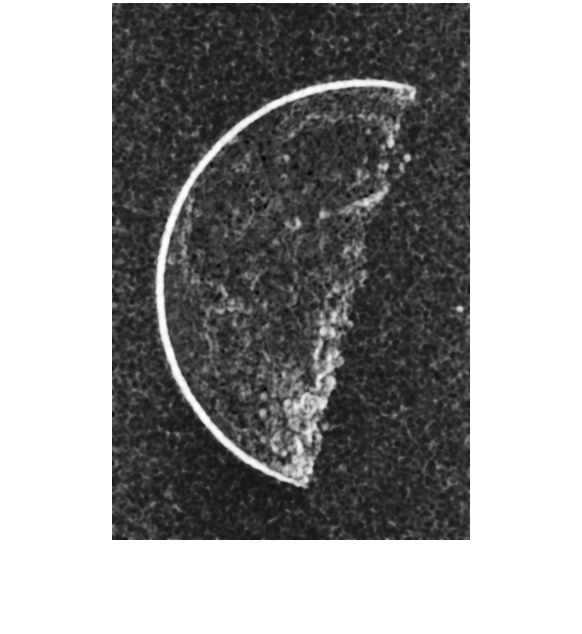

[ssimval,ssimmap] = ssim(Jg,I);
% figure('Name','Local SSIM Map');
figure
imshow(ssimmap,[])

% title(['Local SSIM Map with Global SSIM Value: ',num2str(ssimval)])  % Commented out due to figure "bug"
fprintf('\n The Global SSIM Value is %0.6f \n', ssimval);


 The Global SSIM Value is 0.177590 


Blind/Referenceless Image Spatial Quality Evaluator ([`brisque`](https://www.mathworks.com/help/images/ref/brisque.html)), no-reference image quality score

brisqueI = brisque(I);
fprintf('\nBRISQUE score for original image is %0.4f.\n',brisqueI)


BRISQUE score for original image is 14.0315.



brisqueJg = brisque(Jg);
fprintf('BRISQUE score for noisy (Gaussian) image is %0.4f.\n',brisqueJg)

BRISQUE score for noisy (Gaussian) image is 44.2825.



brisqueJsp = brisque(Jsp);
fprintf('BRISQUE score for noisy (Salt & Pepper) image is %0.4f.\n',brisqueJsp)

BRISQUE score for noisy (Salt & Pepper) image is 47.3591.


Naturalness Image Quality Evaluator ([`niqe`](https://www.mathworks.com/help/images/ref/niqe.html)), no-reference image quality score

niqeI = niqe(I);
fprintf('\nNIQE score for original image is %0.4f.\n',niqeI)


NIQE score for original image is 2.8985.



niqeJg = niqe(Jg);
fprintf('NIQE score for noisy (Gaussian) image is %0.4f.\n',niqeJg)

NIQE score for noisy (Gaussian) image is 17.5242.



niqeJsp = niqe(Jsp);
fprintf('NIQE score for noisy (Salt & Pepper) image is %0.4f.\n',niqeJsp)

NIQE score for noisy (Salt & Pepper) image is 20.7277.


Perception based Image Quality Evaluator ([`piqe`](https://www.mathworks.com/help/images/ref/piqe.html)), no-reference image quality score

piqeI = piqe(I);
fprintf('\nPIQE score for original image is %0.4f.\n',piqeI)


PIQE score for original image is 23.1441.



piqeJg = piqe(Jg);
fprintf('PIQE score for noisy (Gaussian) image is %0.4f.\n',piqeJg)

PIQE score for noisy (Gaussian) image is 74.9360.



piqeJsp = piqe(Jsp);
fprintf('PIQE score for noisy (Salt & Pepper) image is %0.4f.\n',piqeJsp)

PIQE score for noisy (Salt & Pepper) image is 73.3032.


#### **Your turn (step 3 of the guidelines):**

(OPTIONAL) Expand "Part 1" of the starter code to include other test images, noise types (and their parameters) and image quality metrics.

% ENTER YOUR CODE HERE
% ...
% ...
% ...

Go back to top

## Part 2: Denoising using pretrained deep neural network 

There are many ways to remove noise from images. The simplest workflow for removing image noise from an individual image using deep learning is to use a pretrained denoising neural network (`DnCNN`), and is illustrated in the figure below. 

Please refer to [MATLAB documentation](https://www.mathworks.com/help/images/train-and-apply-denoising-neural-networks.html) for more details.

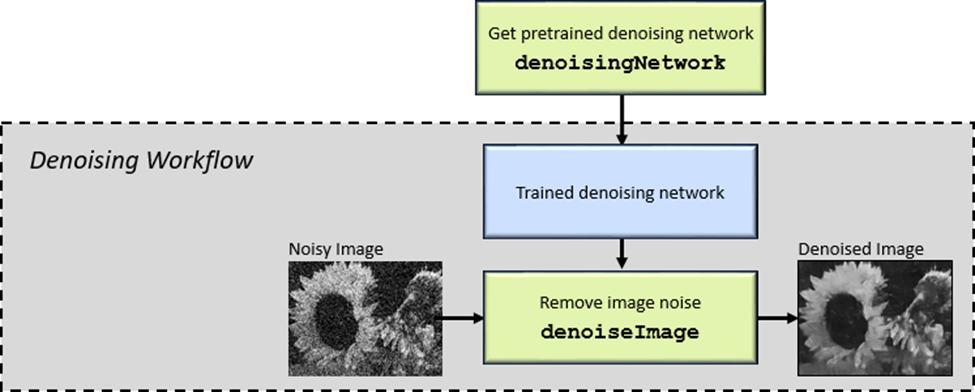

**Suggested steps:**

- Load test image, covert it to appropriate class (if needed) and split it into R, G, and B channels. 

- Load the pretrained DnCNN network.

- Use the DnCNN network to remove noise from each color channel.

- Recombine the denoised color channels to form the denoised RGB image.

- Display the original, noisy, and denoised color image.

- (OPTIONAL) Explore the details of the denoising convolutional neural network (DnCNN).

**Example code:**

Run this section of the starter code and ensure it works as intended. 

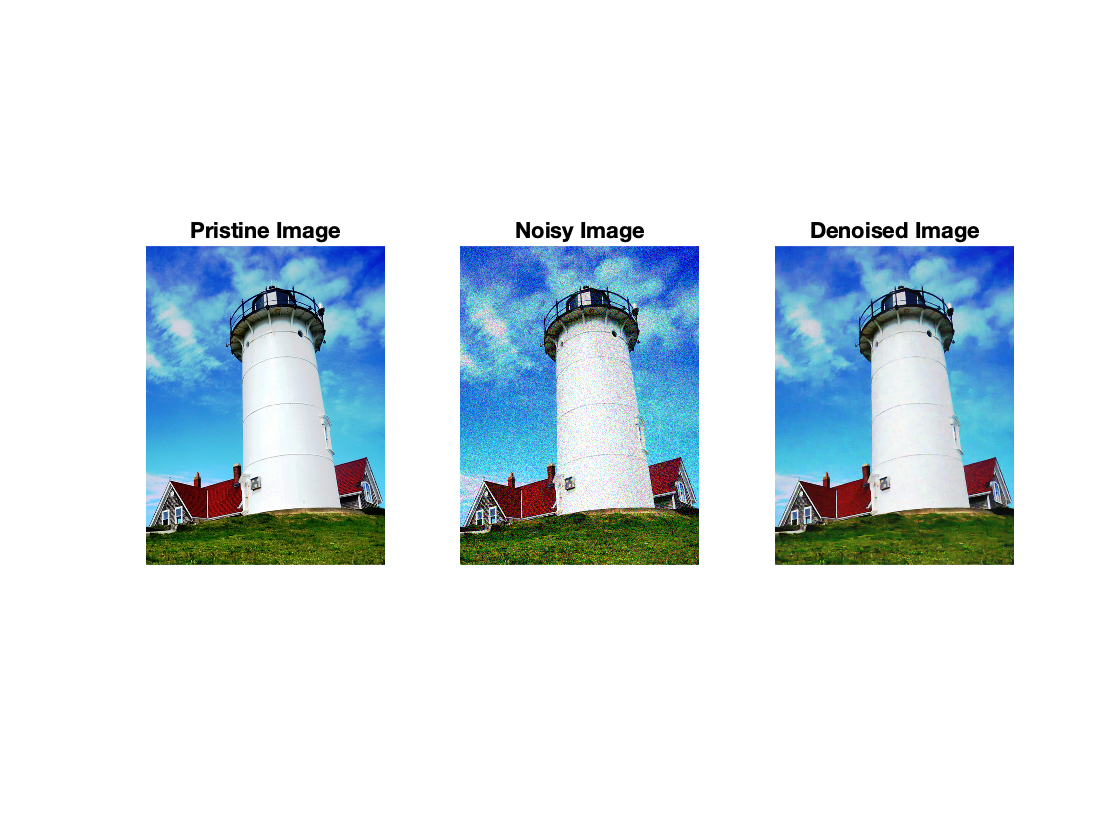

% Load RGB image
pristineRGB = imread('lighthouse.png');
% Convert to double
pristineRGB = im2double(pristineRGB);
% Add Gaussian noise
noisyRGB = imnoise(pristineRGB,'gaussian',0,0.01);

% Split the noisy RGB image into its individual color channels.
[noisyR,noisyG,noisyB] = imsplit(noisyRGB);

% Load the pretrained DnCNN network
preTrainedDnCNN = denoisingNetwork('dncnn');

% Use the DnCNN network to remove noise from each color channel
denoisedR = denoiseImage(noisyR,preTrainedDnCNN);
denoisedG = denoiseImage(noisyG,preTrainedDnCNN);
denoisedB = denoiseImage(noisyB,preTrainedDnCNN);

% Recombine the denoised color channels to form the denoised RGB image
denoisedRGB = cat(3,denoisedR,denoisedG,denoisedB);

% Display the original, noisy, and denoised color image
figure('Name','Denoising with pretrained DnCNN');
subplot(1,3,1), imshow(pristineRGB), title('Pristine Image')
subplot(1,3,2), imshow(noisyRGB), title('Noisy Image')
subplot(1,3,3), imshow(denoisedRGB), title('Denoised Image')

#### **Your turn (step 5 of the guidelines):**

Write code to apply the DnCNN-based denoising technique of "Part 2" to at least 2 (two) different test images of your choice, using both Gaussian and salt-and-pepper noise, and compare their results using at least 2 (two) image quality metrics. 

Summarize your results in a table (see *Guidelines* for additional information).

% ENTER YOUR CODE HERE
% ...
% ...
% ...

#### **Your turn (step 7 of the guidelines): **

(OPTIONAL) Add code to inspect/analyze the selected pretrained neural network in more detail.

% ENTER YOUR CODE HERE
% ...

Go back to top

## Part 3: Training your own denoising network

In this part, we will move to a more comprehensive workflow, where you will train your denoising network from scratch before using it, as illustrated in the figure below. 

Please refer to [MATLAB documentation](https://www.mathworks.com/help/images/train-and-apply-denoising-neural-networks.html) for more details.  

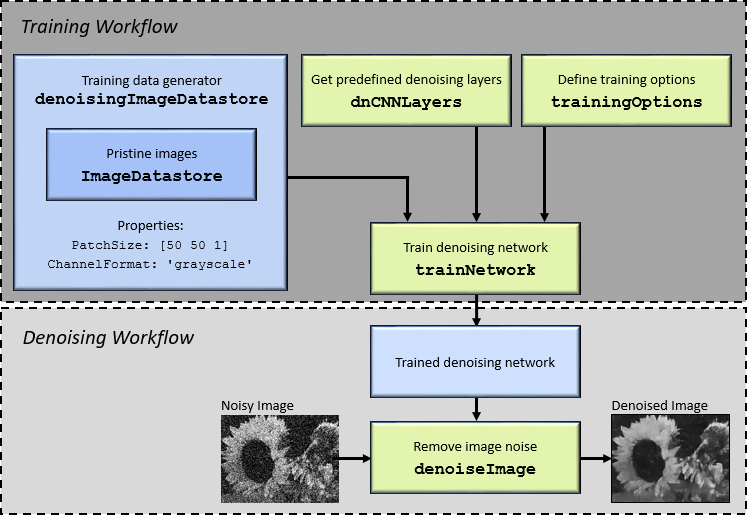

**Note****: this is a very time-consuming operation that can only be successfully completed if you have powerful GPUs. **

**Suggested steps:**

- Create an `imageDatastore` object that stores pristine images.

- Create a `denoisingImageDatastore` object.

- Get the predefined denoising layers using the `dnCNNLayers` function. 

- Define training options.

- Train the network.

- Test and compare with the network in Part 2.

**Step 1:** Create an `imageDatastore` object that stores pristine images. We will use 984 color images of flowers (tulips), of size `224x224` pixels.

imds2 = imageDatastore(fullfile('tulip'),...
'IncludeSubfolders',true,'FileExtensions','.jpg','LabelSource','foldernames');

**Step 2**: Create a `denoisingImageDatastore` object

`denoisingImageDatastore(`[`imds`](https://localhost:31515/static/help/images/ref/denoisingimagedatastore.html#d120e41165)`)` creates a denoising image datastore, `dnimds` using images from image datastore `imds`. To generate noisy image patches, the denoising image datastore randomly crops pristine images from `imds `then adds zero-mean Gaussian white noise with a standard deviation of `0.1` to the image patches.

dnimds2 = denoisingImageDatastore(imds2,'PatchSize', 50, 'ChannelFormat', 'grayscale');

Error using imageDatastore (line 138)
Cannot find files or folders matching: 'tulip'.

**Step 3:** Get the predefined denoising layers using the `dnCNNLayers` function

layers2 = dnCNNLayers;

**Step 4:** Define training options

options = trainingOptions('adam', ...
    'InitialLearnRate',0.1, ...
    'LearnRateSchedule',"none", ...
    'MiniBatchSize',256, ...
    'MaxEpochs',2, ...
    'Plots','training-progress', ...
    'Verbose',false);

**Step 5:** Train the network

dnCNN2 = trainNetwork(dnimds2,layers2,options);

**Step 6**: Test and compare with the network in Part 2.

% Load RGB image
pristineRGB = imread('lighthouse.png');
% Convert to double
pristineRGB = im2double(pristineRGB);
% Add Gaussian noise
noisyRGB = imnoise(pristineRGB,'gaussian',0,0.01);

% Split the noisy RGB image into its individual color channels.
[noisyR,noisyG,noisyB] = imsplit(noisyRGB);

% Use the DnCNN2 network to remove noise from each color channel
denoisedR2 = denoiseImage(noisyR,dnCNN2);
denoisedG2 = denoiseImage(noisyG,dnCNN2);
denoisedB2 = denoiseImage(noisyB,dnCNN2);

% Recombine the denoised color channels to form the denoised RGB image
denoisedRGB2 = cat(3,denoisedR2,denoisedG2,denoisedB2);

% Display the original, noisy, and denoised color image
figure('Name','Denoising with DnCNN trained from scratch');
subplot(1,3,1), imshow(pristineRGB), title('Pristine Image')
subplot(1,3,2), imshow(noisyRGB), title('Noisy Image')
subplot(1,3,3), imshow(denoisedRGB2), title('Denoised Image')

#### **Your turn (step 10 of the guidelines): **

Write code to apply the DnCNN-based denoising technique of "Part 3" to at least 2 (two) different test images of your choice, using both Gaussian and salt-and-pepper noise, and compare their results using at least 2 (two) image quality metrics. 

Summarize your results in a table (see *Guidelines* for additional information).

% ENTER YOUR CODE HERE
% ...
% ...
% ...

Go back to top

## Part 4: (OPTIONAL) Denoising using autoencoders

In this part, we will use a convolutional autoencoder architecture for denoising and apply it to images from a built-in dataset containing handwritten digits (similar to MNIST).

Please refer to [MATLAB documentation](https://www.mathworks.com/help/deeplearning/autoencoders.html) for more details.

**Suggested steps:**

- Load test images and add noise. 

- Prepare the data for network training, validation, and testing.

- Visualize the images before and after adding noise. 

- Define a convolutional autoencoder network.

- Train the network.

- (Visually) evaluate the results.

- Measure the quality of the resulting (denoised) image (and compare with the original).

**Example code:**

Based on (and adapted from): [https://www.mathworks.com/help/deeplearning/ug/image-to-image-regression-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/image-to-image-regression-using-deep-learning.html) 

Notes:

- The datastore contains 10,000 synthetic images of digits from 0 to 9.

- The images are generated by applying random transformations to digit images created with different fonts.

- Each digit image is 28-by-28 pixels. 

- The datastore contains an equal number of images per category.

**Build **`imds`

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet', ...
    'nndemos','nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

imds.ReadSize = 500;
rng(0)
imds = shuffle(imds);

**Split **`imds`** into three image datastores containing pristine images for training, validation, and testing**

[imdsTrain,imdsVal,imdsTest] = splitEachLabel(imds,0.95,0.025);

**Create noisy versions of each input image** using the helper function `addNoise` (see [https://www.mathworks.com/help/deeplearning/ug/image-to-image-regression-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/image-to-image-regression-using-deep-learning.html))

dsTrainNoisy = transform(imdsTrain,@addNoise);
dsValNoisy = transform(imdsVal,@addNoise);
dsTestNoisy = transform(imdsTest,@addNoise);

**Combine the noisy images and pristine images into a single datastore that feeds data to **`trainNetwork`

This combined datastore reads batches of data into a two-column cell array as expected by `trainNetwork`. 

dsTrain = combine(dsTrainNoisy,imdsTrain);
dsVal = combine(dsValNoisy,imdsVal);
dsTest = combine(dsTestNoisy,imdsTest);

**Perform additional preprocessing operations that are common to both the input and response datastores**

The `commonPreprocessing` helper function (see [https://www.mathworks.com/help/deeplearning/ug/image-to-image-regression-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/image-to-image-regression-using-deep-learning.html)) resizes input and response images to 32-by-32 pixels to match the input size of the network, and normalizes the data in each image to the range [0, 1].

dsTrain = transform(dsTrain,@commonPreprocessing);
dsVal = transform(dsVal,@commonPreprocessing);
dsTest = transform(dsTest,@commonPreprocessing);

**Perform image data augmentation**

The `augmentImages` helper function (see [https://www.mathworks.com/help/deeplearning/ug/image-to-image-regression-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/image-to-image-regression-using-deep-learning.html)) applies randomized 90 degree rotations to the data. Identical rotations are applied to the network input and corresponding expected responses.

dsTrain = transform(dsTrain,@augmentImages);

**Preview preprocessed data**

The code below shows examples of paired noisy and pristine images using the `montage` function. 

The training data looks correct. Salt and pepper noise appears in the input images in the left column. Randomized 90 degree rotation is applied to both input and response images in the same way.

exampleData = preview(dsTrain);
inputs = exampleData(:,1);
responses = exampleData(:,2);
minibatch = cat(2,inputs,responses);
figure
montage(minibatch','Size',[8 2])
title('Inputs (Left) and Responses (Right)')

**Define convolutional autoencoder network**

See [https://www.mathworks.com/help/deeplearning/ug/image-to-image-regression-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/image-to-image-regression-using-deep-learning.html) for details.

imageLayer = imageInputLayer([32,32,1]);

encodingLayers = [ ...
    convolution2dLayer(3,16,'Padding','same'), ...
    reluLayer, ...
    maxPooling2dLayer(2,'Padding','same','Stride',2), ...
    convolution2dLayer(3,8,'Padding','same'), ...
    reluLayer, ...
    maxPooling2dLayer(2,'Padding','same','Stride',2), ...
    convolution2dLayer(3,8,'Padding','same'), ...
    reluLayer, ...
    maxPooling2dLayer(2,'Padding','same','Stride',2)];

decodingLayers = [ ...
    createUpsampleTransponseConvLayer(2,8), ...
    reluLayer, ...
    createUpsampleTransponseConvLayer(2,8), ...
    reluLayer, ...
    createUpsampleTransponseConvLayer(2,16), ...
    reluLayer, ...
    convolution2dLayer(3,1,'Padding','same'), ...
    clippedReluLayer(1.0), ...
    regressionLayer];    

layers = [imageLayer,encodingLayers,decodingLayers];

**Define training options**

options = trainingOptions('adam', ...
    'MaxEpochs',30, ...
    'MiniBatchSize',imds.ReadSize, ...
    'ValidationData',dsVal, ...
    'Shuffle','never', ...
    'Plots','training-progress', ...
    'Verbose',false);

**Train the network**

autoEncoder = trainNetwork(dsTrain,layers,options);

**Evaluate the performance of the network on the test set**

ypred = predict(autoEncoder,dsTest);

**Perform visual inspection of selected results**

inputImageExamples = preview(dsTest);
figure
montage({inputImageExamples{1},ypred(:,:,:,1)});

**Calculate PSNR**

ref = inputImageExamples{1,2};
originalNoisyImage = inputImageExamples{1,1};
psnrNoisy = psnr(originalNoisyImage,ref);
psnrDenoised = psnr(ypred(:,:,:,1),ref);

fprintf('\nThe PSNR of the noisy image is %.4f', psnrNoisy); 
fprintf('\nThe PSNR of the denoised image is %.4f\n', psnrDenoised);

**Calculate PIQE**

piqeNoisy = piqe(originalNoisyImage);
piqeDenoised = piqe(ypred(:,:,:,1));

fprintf('\nThe PIQE of the noisy image is %.4f', piqeNoisy); 
fprintf('\nThe PIQE of the denoised image is %.4f\n', piqeDenoised);

#### **Your turn (step 16 of the guidelines): **

(OPTIONAL) Write code to compute other figures of merit for selected images.

% ENTER YOUR CODE HERE
% ...
% ...

Go back to top

% Helper functions

% function dataOut = addNoise(data)
%     dataOut = data;
%     for idx = 1:size(data,1)
%        dataOut{idx} = imnoise(data{idx},'salt & pepper');
%     end
% end
% 
% function dataOut = commonPreprocessing(data)
%     dataOut = cell(size(data));
%     for col = 1:size(data,2)
%         for idx = 1:size(data,1)
%             temp = single(data{idx,col});
%             temp = imresize(temp,[32,32]);
%             temp = rescale(temp);
%             dataOut{idx,col} = temp;
%         end
%     end
% end
% 
% function dataOut = augmentImages(data)
%     dataOut = cell(size(data));
%     for idx = 1:size(data,1)
%         rot90Val = randi(4,1,1)-1;
%         dataOut(idx,:) = {rot90(data{idx,1},rot90Val),rot90(data{idx,2},rot90Val)};
%     end
% end
% 
% function out = createUpsampleTransponseConvLayer(factor,numFilters)
%     filterSize = 2*factor - mod(factor,2); 
%     cropping = (factor-mod(factor,2))/2;
%     numChannels = 1;
%     
%     out = transposedConv2dLayer(filterSize,numFilters, ... 
%         'NumChannels',numChannels,'Stride',factor,'Cropping',cropping);
% end